# interpolazione

se dice polinomio di lagrange usare la fun baricentric nella cartella interpolazione

# ricerca degli zeri

metodo della bisezione

[zero fval iter] = bisezione(f,a,b,tol)

Unrecognized function or variable 'a'.

restituisce:

- zero = x della funzione dove vale zero 

- fval = valore che assume la funzione in zero

- iter numero di iterazioni per trovare lo zero

[zero,fz,iter,xk] = newton(f,x0,toll,Nmax)

#### serve una f definita come syms x dato che poi al suo interno devo calcolare la derivata

syms x
f = x^2-2;

restituisce :

- zero = x della funzione dove vale zero 

- fval = valore che assume la funzione in zero

- iter numero di iterazioni per trovare lo zero

- xk = sequenza di valori utilizzati per il calcolo dello zero

per riportare la succesione dei valori utilizzati fare

plot(xk)

differenza della iterata precedente e successiva nel vettore dif

dif=abs(xk(1:end-1)-xk(2:end));% per vedere la convergengs in scala semilog

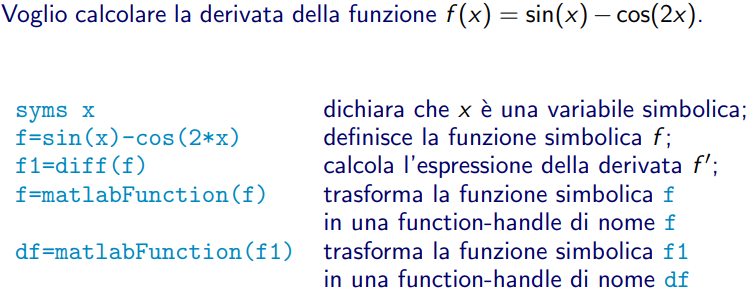

fimplicit % per plottare curve di livello 0 ovvero F =0
F=@(x) [f(x(1),x(2));g(x(1),x(2))];
[zm,fval] = fsolve(F,[0,-1]);% per punti vincolati

per fare la soluzione in un sistema di due o piu equazioni si passa il sistema e un punto di partenza vicino alla soluzione cercata

per trovare i minimi in xy

f = @(x,y) 3*(1-x).*y
F= @(x) f(x(1),x(2))
fminsearch(F,[1.5 0])

 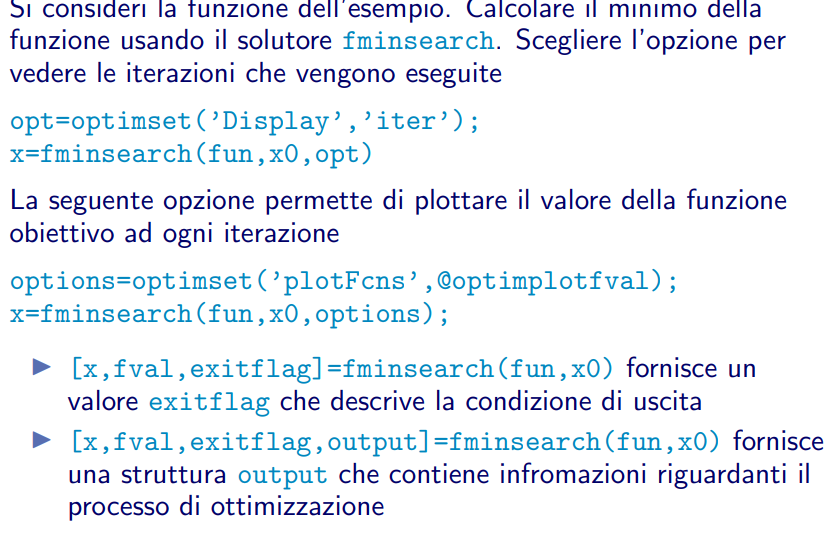

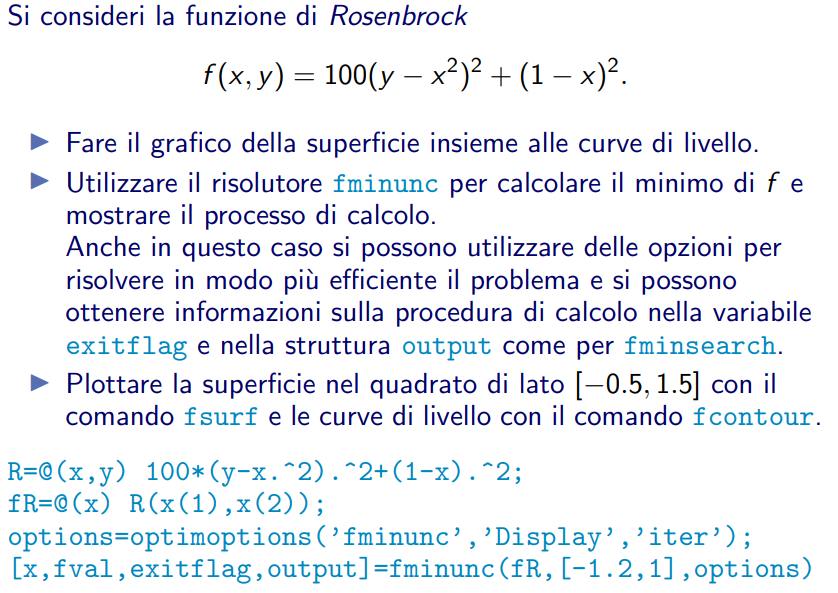

# sistemi lineari

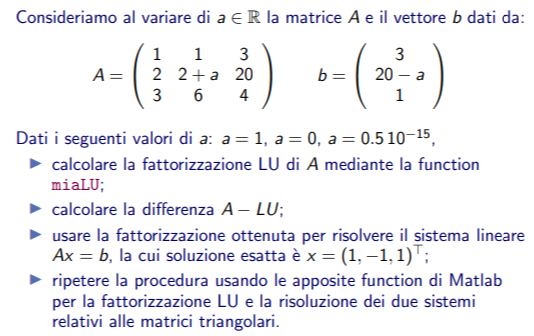

clear
close all
a=1;
%a=0;
%a=0.510^(-15);
A=[1 1 3; 2 2+a 20; 3 6 4];
B=[3; 20-a; 1];
%calcolo la fattorizzazione LU senza pivoting di A --> L e U triangolari
%inferiore e superiore
[L,U]=miaLU(A);
diff=A-L*U; %con miaLU ottengo 0 spaccato
x=A\B
%rifaccio usando Lu (con pivoting) e la risoluzione di Ly=B e Ux=y
[L1,U1]=lu(A);
y=L1\B;
x_pivot=U1\y